## TS3

P1 sistema de producción industrial

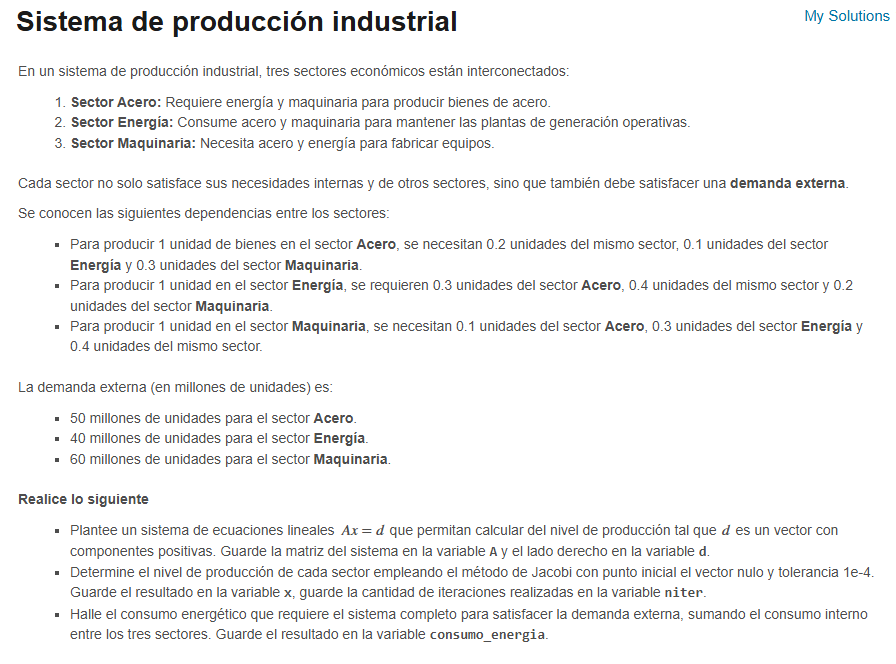

% A: matriz del sistema, d: lado derecho

A = [0.8 -0.1 -0.3; -0.3 0.6 -0.2; -0.1 -0.3 0.6]

A =    0.800000000000000  -0.100000000000000  -0.300000000000000
  -0.300000000000000   0.600000000000000  -0.200000000000000
  -0.100000000000000  -0.300000000000000   0.600000000000000


d = [50; 40; 60];

% Aplique el  método de Jacobi
Tol = 1e-4;
x0 = [0;0;0] % Punto inicial en cero

x0 =      0
     0
     0



[z,x] = jacobi(A,d,x0,Tol)

z = 1.0e+02 *

                   0                   0                   0                   0   0.010000000000000
   0.010000000000000   0.625000000000000   0.666666666666667   1.000000000000000   0.010000000000000
   0.020000000000000   1.083333333333333   1.312500000000000   1.437500000000000   0.004492753623188
   0.030000000000000   1.328125000000000   1.687500000000000   1.836805555555555   0.002173913043478
   0.040000000000000   1.524739583333333   1.942997685185185   2.065104166666667   0.001237214515903
   0.050000000000000   1.642288773148148   2.117404513888889   2.225622106481481   0.000783631813306
   0.060000000000000   1.724283854166667   2.229685088734568   2.332417052469136   0.000481391502119
   0.070000000000000   1.778367030767747   2.306280944573045   2.402223186728395   0.000318854035968
   0.080000000000000   1.814118813094779   2.356591244293339   2.449534977414481   0.000205387145659
   0.090000000000000   1.838149522067098   2.390237732352217   2.48064875766

x = 1.0e+02 *

   1.885354707178674
   2.456637468268306
   2.542387421777398



niter = 21

niter =     21


% Halle el consumo energético
consumo_energia = 50*x(1) + 40*x(2) + 60*x(3)

consumo_energia =      3.450764793963098e+04


%{
function [z,x1] = jacobi(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tj = inv(D)*(L+U);
    cj = inv(D)*b;
    i = 0;
    z = [i x0' dr];
    while(dr>Tol)
        % Método Numérico
        x1 = Tj*x0 + cj;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end
%}


P2

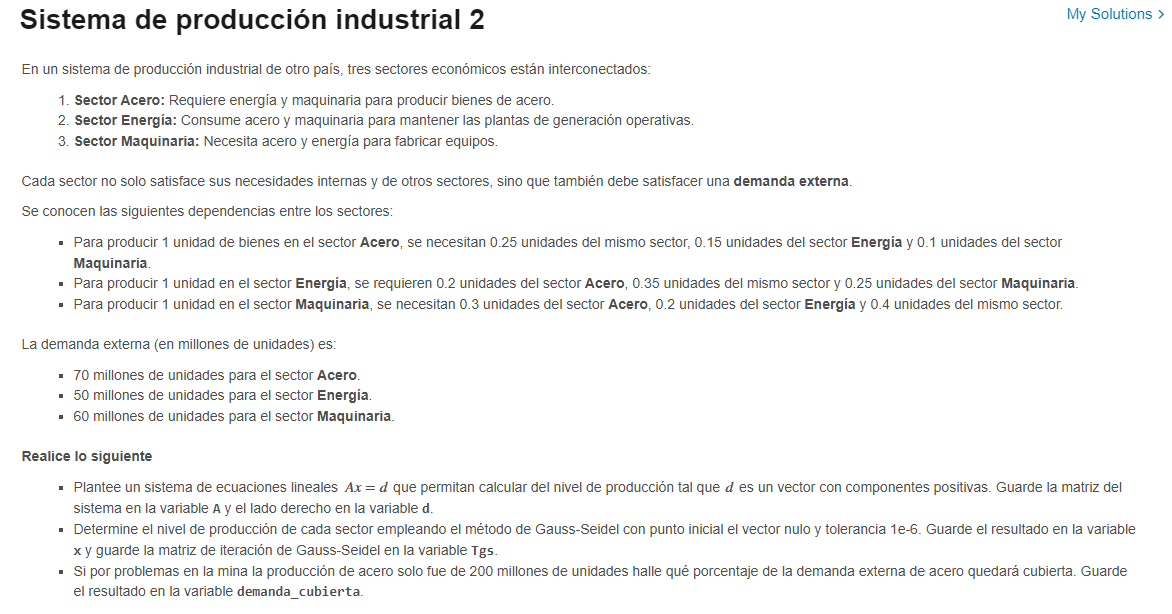

A = [0.75 -0.15 -0.1;
    -0.2 0.65 -0.25;
    -0.3 -0.2 0.6]

A =    0.750000000000000  -0.150000000000000  -0.100000000000000
  -0.200000000000000   0.650000000000000  -0.250000000000000
  -0.300000000000000  -0.200000000000000   0.600000000000000


d = [70; 50; 60]

d =     70
    50
    60



% Aplique el método de Gauss-Seidel
Tol = 1e-6;
x0 = [0;0;0]; 

[Tgs, x] = gauss_seidel(A, d, x0, Tol)

Tgs = 1.0e+02 *

                   0                   0                   0                   0   0.010000000000000
   0.010000000000000   0.933333333333333   1.056410256410256   1.818803418803419   0.010000000000000
   0.020000000000000   1.387122507122507   1.895577470962086   2.325420410548616   0.003608668827130
   0.030000000000000   1.622504882265566   2.162855506292719   2.532204276563689   0.001055515298684
   0.040000000000000   1.703531671467036   2.267319082206661   2.607538863135738   0.000400621357521
   0.050000000000000   1.734468998192764   2.305813100649980   2.635838865979709   0.000146040863651
   0.060000000000000   1.745941135593957   2.320227605559567   2.646379769650168   0.000054468769278
   0.070000000000000   1.750229490398602   2.325601293065019   2.650315176220975   0.000020275654585
   0.080000000000000   1.751828948775800   2.327607052016006   2.651783491726569   0.000007563811138
   0.090000000000000   1.752425875966743   2.328355458653832   2.652331424

x = 1.0e+02 *

   1.752780252004041
   2.328799785999084
   2.652656721335048



demanda_cubierta = (x(1) / 200) * 100

demanda_cubierta =   87.639012600202022


%{
function [z,x1] = gauss_seidel(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tgs = inv(D-L)*(U);
    cgs = inv(D-L)*b;
    i = 0;
    z = [i x0' dr];
    while(dr>Tol)
        % Método Numérico
        x1 = Tgs*x0 + cgs;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end
%}


P3

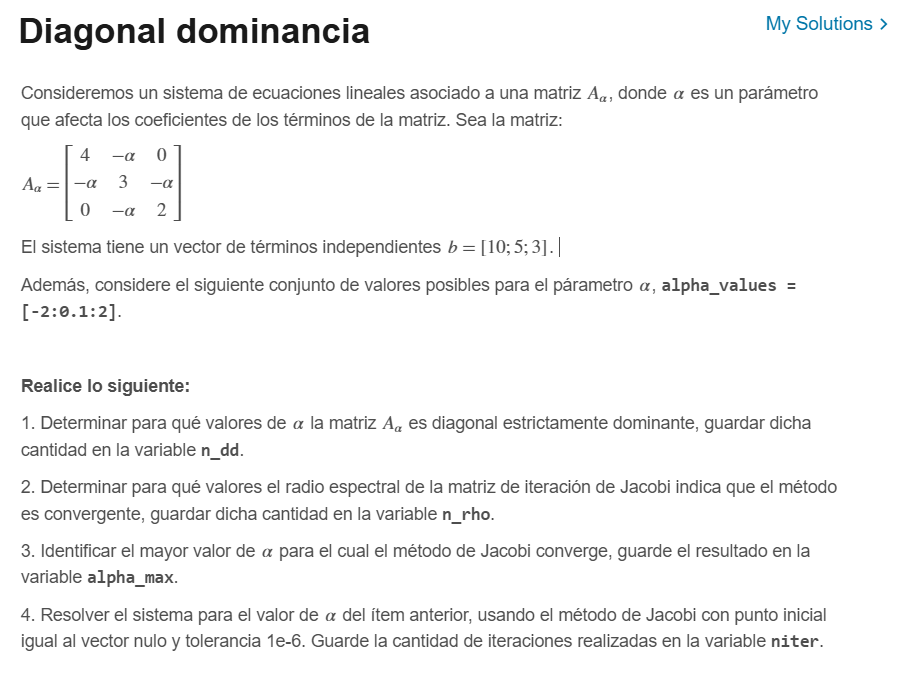

% Parámetros iniciales
alpha_values = -2:0.1:2; 
b = [10; 5; 3];  

% Variables para almacenar resultados
n_dd = 0;
n_rho = 0;
alpha_max = NaN;

Tol = 1e-6;
x0 = zeros(size(b));

for alpha = alpha_values
    % Matriz A_alpha
    A_alpha = [4, -alpha, 0; -alpha, 3, -alpha; 0, -alpha, 2];
    
    % Chequeo de diagonal dominante
    if all(2*abs(diag(A_alpha)) > sum(abs(A_alpha), 2))
        n_dd = n_dd + 1;
    end
    
    % Radio espectral de la matriz de iteración de Jacobi
    D = diag(diag(A_alpha));
    L = -tril(A_alpha, -1);
    U = -triu(A_alpha, 1);
    Tj = inv(D) * (L + U);
    rho = max(abs(eig(Tj)));
    
    if rho < 1
        n_rho = n_rho + 1;
        if isnan(alpha_max) || alpha > alpha_max
            alpha_max = alpha;
        end
    end
end

% Resolver el sistema para el valor de alpha_max usando la función de Jacobi proporcionada

A_alpha = [4, -alpha_max, 0; -alpha_max, 3, -alpha_max; 0, -alpha_max, 2];
    
[z, x1] = jacobi(A_alpha, b, x0, Tol);
niter = size(z, 1) - 1;  % Número de iteraciones


% Resultados
n_dd

n_dd =     29


n_rho

n_rho =     39


alpha_max

alpha_max =    1.900000000000000


niter

niter =    217



%{
function [z,x1] = jacobi(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tj = inv(D)*(L+U);
    cj = inv(D)*b;
    i = 0;
    z = [i x0' dr];
    while(dr>Tol)
        % Método Numérico
        x1 = Tj*x0 + cj;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end
%}


P4

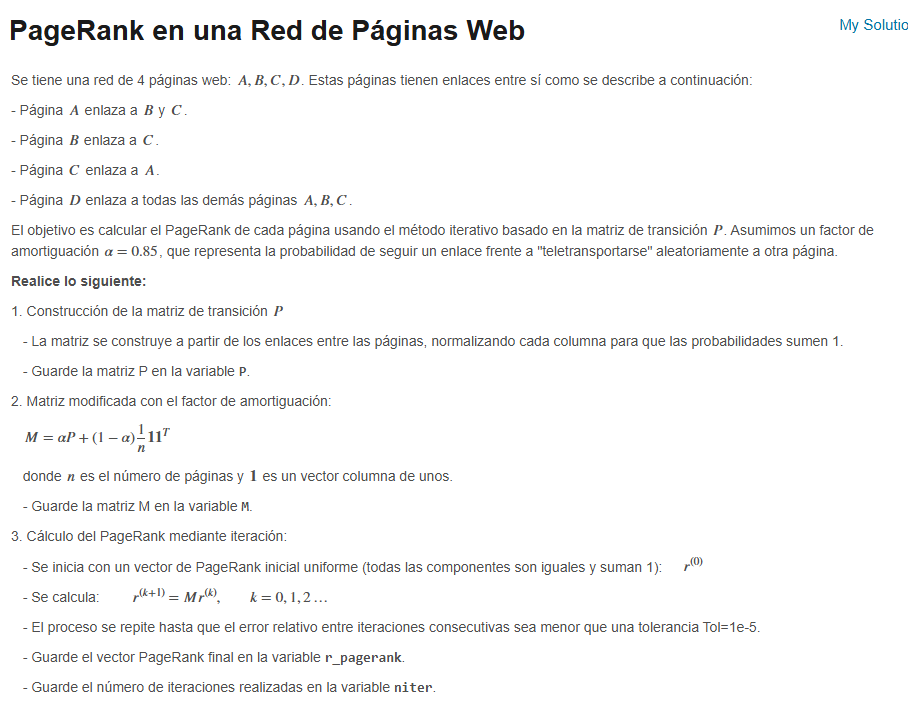

n = 4;

P = [0    0    1    1/3; 
     1/2  0    0    1/3; 
     1/2  1    0    1/3; 
     0    0    0    0]

P =                    0                   0   1.000000000000000   0.333333333333333
   0.500000000000000                   0                   0   0.333333333333333
   0.500000000000000   1.000000000000000                   0   0.333333333333333
                   0                   0                   0                   0



% Matriz modificada
alpha = 0.85;

e = ones(n, 1);

M = alpha * P + (1 - alpha) * (1/n) * (e * e')

M =    0.037500000000000   0.037500000000000   0.887500000000000   0.320833333333333
   0.462500000000000   0.037500000000000   0.037500000000000   0.320833333333333
   0.462500000000000   0.887500000000000   0.037500000000000   0.320833333333333
   0.037500000000000   0.037500000000000   0.037500000000000   0.037500000000000



% Iteraciones de PageRank
Tol = 1e-5;    
r = ones(n, 1) / n

r =    0.250000000000000
   0.250000000000000
   0.250000000000000
   0.250000000000000


error = 1;
niter = 0;

while error > Tol
    r_new = M * r;
    error = norm(r_new - r, inf) / norm(r_new, inf);
    r = r_new;
    niter = niter + 1;
end

r_pagerank = r

r_pagerank =    0.373246163022632
   0.206756072116468
   0.382497764860900
   0.037500000000000


niter

niter =     22


p5

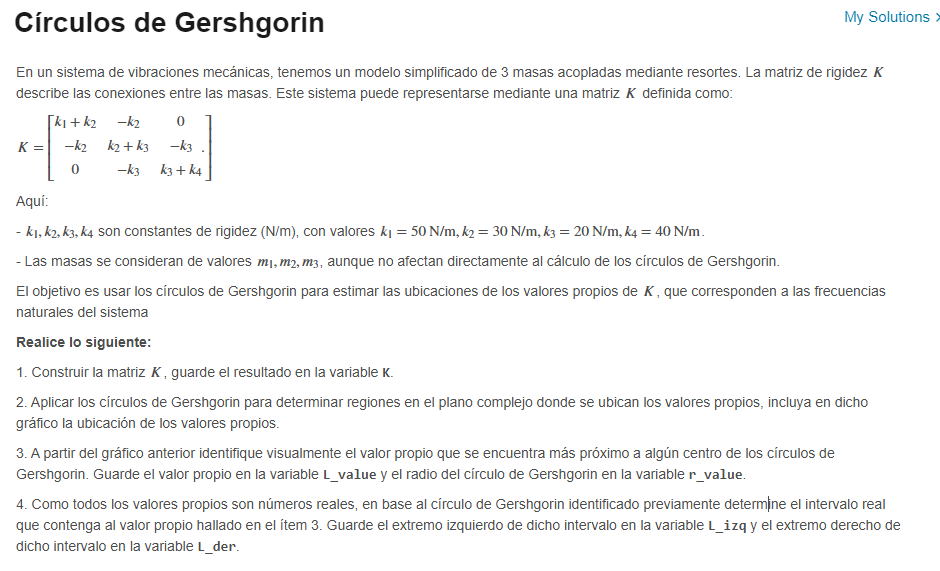

k1 = 50; k2 = 30; k3 = 20; k4 = 40;
K = [k1+k2, -k2, 0;
    -k2, k2+k3, -k3;
    0, -k3, k3+k4]

K =     80   -30     0
   -30    50   -20
     0   -20    60



% Calcular los valores propios reales
eig_values = eig(K)

eig_values = 1.0e+02 *

   0.232541984504371
   0.652461100049763
   1.014996915445866


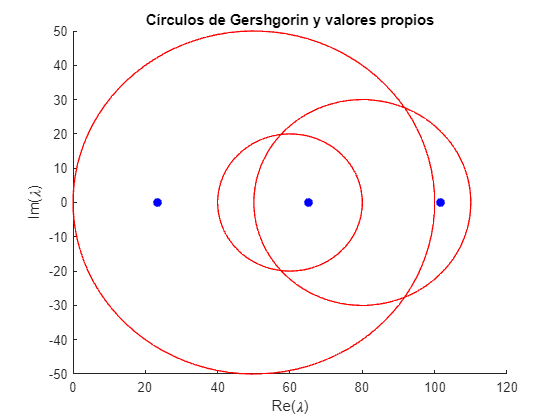


% Visualización de los círculos de Gershgorin
figure;
theta = linspace(0, 2*pi, 100);
hold on;
for i = 1:length(K)
    center = K(i, i);
    radius = sum(abs(K(i, :))) - abs(K(i, i));
    plot(center + radius*cos(theta), radius*sin(theta), 'r');
end
plot(eig_values, zeros(size(eig_values)), 'bo', 'MarkerFaceColor', 'b'); % Valores propios
hold off;
xlabel('Re(\lambda)');
ylabel('Im(\lambda)');
title('Círculos de Gershgorin y valores propios');


% Valor propio más cercano a un círculo de Gershgorin
[~, idx] = min(abs(diag(K) - eig_values));
L_value = eig_values(idx)

L_value =   65.246110004976316



% Círculo de Gershgorin correspondiente
r_value = 20

r_value =     20



% Intervalo del valor propio más próximo a un centro de los círculos de Gershgorin
L_izq = 40

L_izq =     40


L_der = 80

L_der =     80


## P6

## 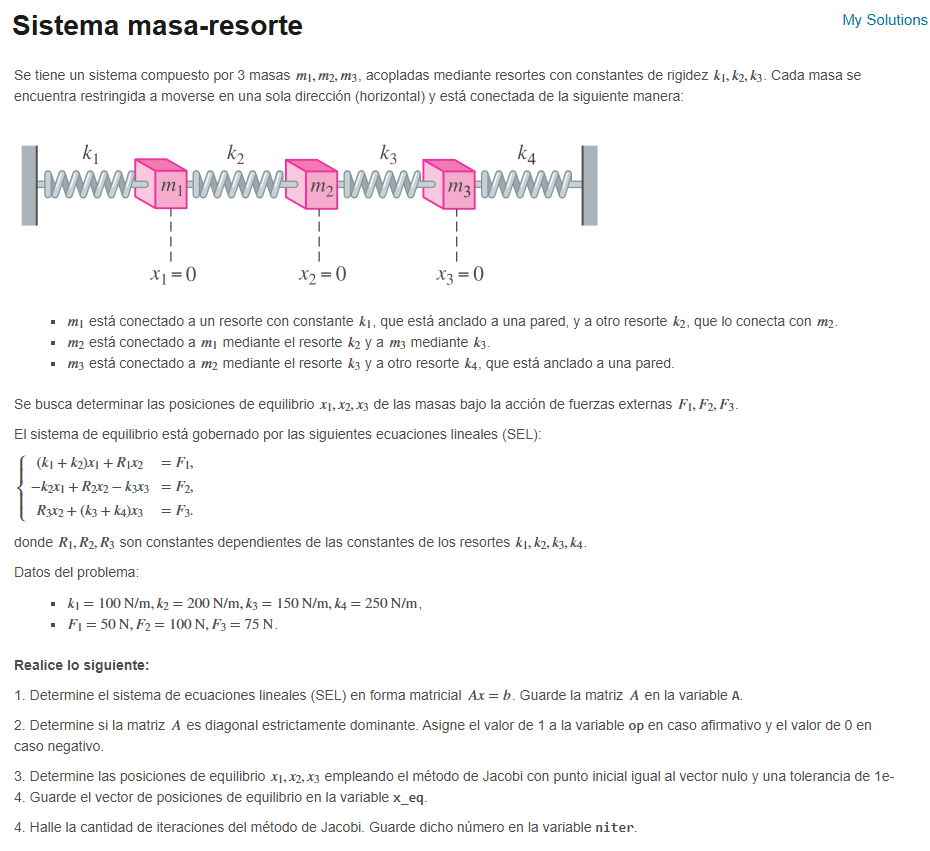

% Datos del problema
k1 = 100; k2 = 200; k3 = 150; k4 = 250;
b = [50; 100; 75]; % Fuerzas externas

% Construcción de la matriz del sistema
A = [k1 + k2, -k2, 0;
    -k2, k2 + k3, -k3;
    0, -k3, k3 + k4]

A =    300  -200     0
  -200   350  -150
     0  -150   400



% Diagonal dominancia
op = 0

op =      0



% Método de Jacobi
Tol = 1e-4;
x0 = zeros(size(b)); % Punto inicial
[z, x_eq] = jacobi(A, b, x0, Tol)

z =                    0                   0                   0                   0   1.000000000000000
   1.000000000000000   0.166666666666667   0.285714285714286   0.187500000000000   1.000000000000000
   2.000000000000000   0.357142857142857   0.461309523809524   0.294642857142857   0.412903225806452
   3.000000000000000   0.474206349206349   0.616071428571429   0.360491071428571   0.251207729468599
   4.000000000000000   0.577380952380952   0.711185515873016   0.418526785714286   0.145074106364429
   5.000000000000000   0.640790343915344   0.795014880952381   0.454194568452381   0.105443768522851
   6.000000000000000   0.696676587301587   0.846535011574074   0.485630580357143   0.066017639698477
   7.000000000000000   0.731023341049383   0.891942584325397   0.504950629340278   0.050908627471426
   8.000000000000000   0.761295056216931   0.919849321745481   0.521978469122024   0.032909428155153
   9.000000000000000   0.779899547830320   0.944445090319114   0.532443495654555   0.02

x_eq =    0.837430471616371
   1.006244437482839
   0.564804640284209


niter = size(z, 1) - 1

niter =     27



%{
function [z,x1] = jacobi(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tj = inv(D)*(L+U);
    cj = inv(D)*b;
    i = 0;
    z = [i x0' dr];
    while(dr > Tol)
        % Método Numérico
        x1 = Tj*x0 + cj;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end
%}

## P7

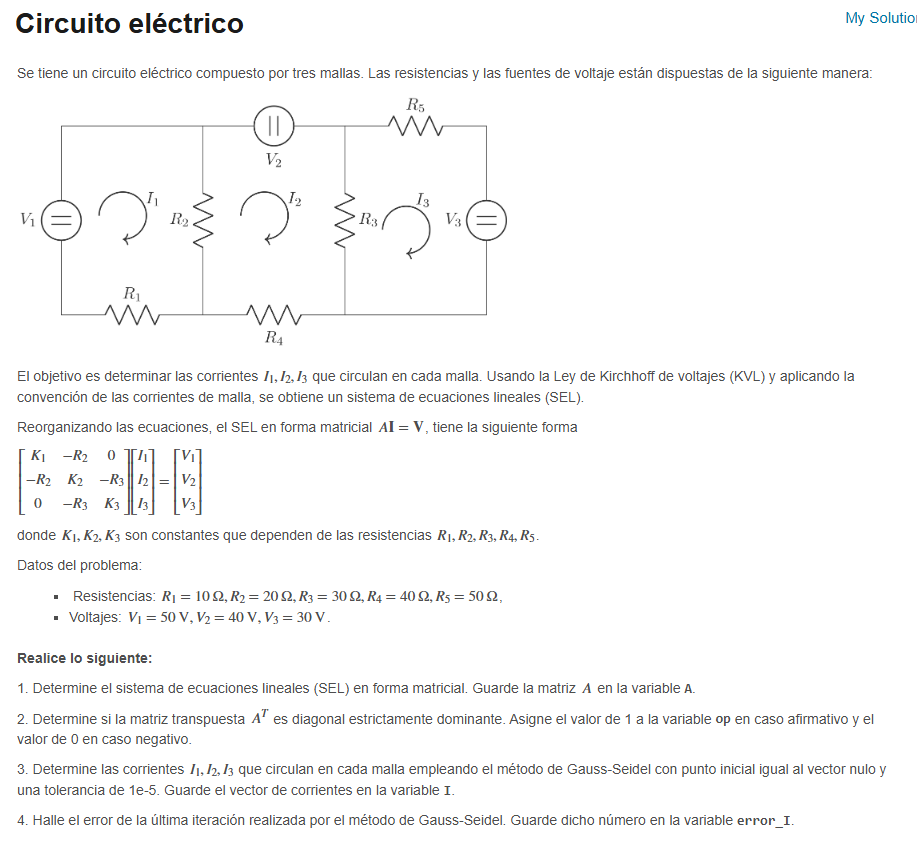

R1 = 10; R2 = 20; R3 = 30; R4 = 40; R5 = 50;
V1 = 50; V2 = 40; V3 = 30;
b = [V1; V2; V3]; % Vector de voltajes

% Construcción de la matriz A
K1 = R1 + R2;
K2 = R2 + R3 + R4;
K3 = R3 + R5;

A = [K1, -R2, 0; -R2, K2, -R3; 0, -R3, K3]

A =     30   -20     0
   -20    90   -30
     0   -30    80



% Diagonal dominancia de A'
A_transpuesta = A'

A_transpuesta =     30   -20     0
   -20    90   -30
     0   -30    80


diagonal_dominante = all(2*abs(diag(A_transpuesta)) > sum(abs(A_transpuesta), 2));
op = double(diagonal_dominante)

op =      1



% Inicialización del método de Gauss-Seidel
Tol = 1e-5;
x0 = [0; 0; 0]; % Vector inicial nulo

% Llamada a la función Gauss-Seidel
[z, I] = gauss_seidel(A, b, x0, Tol)

z =                    0                   0                   0                   0   1.000000000000000
   1.000000000000000   1.666666666666667   0.814814814814815   0.680555555555556   1.000000000000000
   2.000000000000000   2.209876543209877   1.162379972565158   0.810892489711934   0.245810055865922
   3.000000000000000   2.441586648376772   1.257316751765483   0.846493781912056   0.094901446696943
   4.000000000000000   2.504877834510322   1.283248557195201   0.856218208948201   0.025267174814505
   5.000000000000000   2.522165704796801   1.290331781826467   0.858874418184925   0.006854375290886
   6.000000000000000   2.526887854550978   1.292266551517415   0.859599956819030   0.001868761110895
   7.000000000000000   2.528177701011610   1.292795030275590   0.859798136353346   0.000510188211895
   8.000000000000000   2.528530020183727   1.292939383269721   0.859852268726146   0.000139337547628
   9.000000000000000   2.528626255513148   1.292978813022748   0.859867054883531   0.00

I =    2.528659722124513
   1.292992525037127
   0.859872196888923



% Error del método de Gauss-Seidel
error_I = z(end, end)

error_I =      2.839492116991532e-06



% Función del método de Gauss-Seidel
%{
function [z,x1] = gauss_seidel(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tgs = inv(D-L)*(U);
    cgs = inv(D-L)*b;
    i = 0;
    z = [i x0' dr];
    while(dr>Tol)
        % Método Numérico
        x1 = Tgs*x0 + cgs;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end
%}


## P8

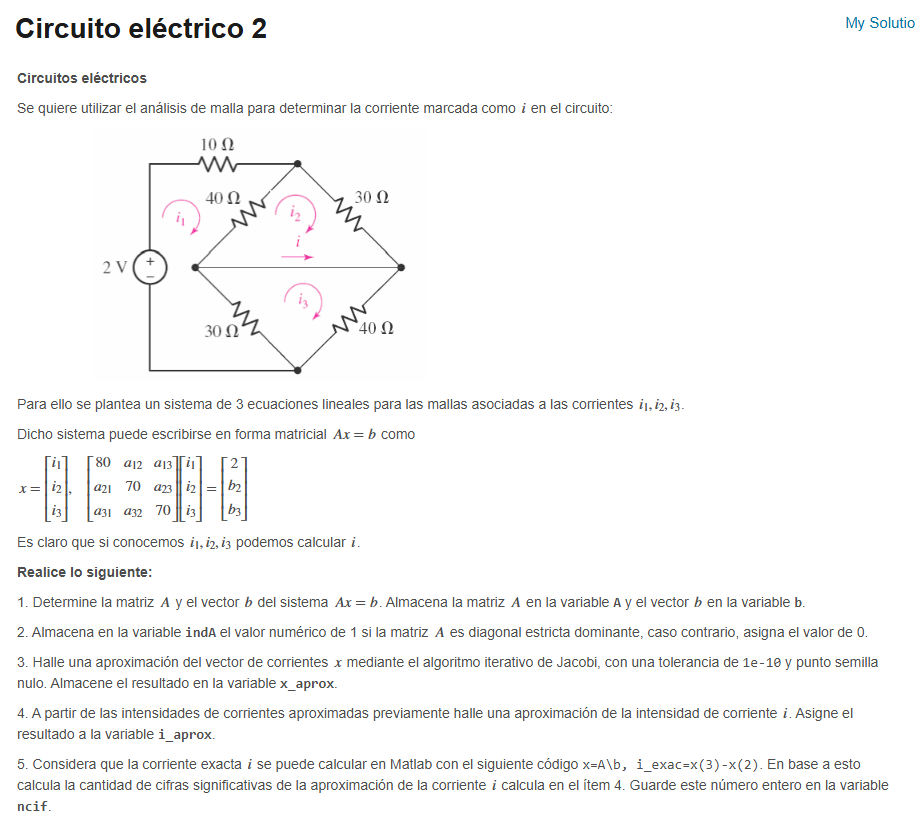

format long

A = [80 -40 -30; -40 70 0; -30 0 70] 

A =     80   -40   -30
   -40    70     0
   -30     0    70


b = [2 ; 0; 0]

b =      2
     0
     0



% Verificar si la matriz A es diagonal estrictamente dominante
indA = 1

indA =      1



% Método iterativo de Jacobi
x0 = zeros(size(b, 1), 1) % Punto semilla

x0 =      0
     0
     0


Tol = 1e-10; % Tolerancia
method = 0; % Método de Jacobi

[~,x_aprox] = jacobi(A, b, x0, Tol);
x_aprox

x_aprox =    0.045161290319436
   0.025806451608878
   0.019354838706659


% Calcular la aproximación de la corriente i
i_aprox = x_aprox(3) - x_aprox(2)

i_aprox =   -0.006451612902220



% Calcular la corriente exacta y el número de cifras sig
x_exact = A \ b;
i_exact = x_exact(3) - x_exact(2)

i_exact =   -0.006451612903226


ncif = 10

ncif =     10



% Mostrar resultados

%{
function [z,x1] = jacobi(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tj = inv(D)*(L+U);
    cj = inv(D)*b;
    i = 0;
    z = [i x0' dr];
    while(dr>Tol)
        % Método Numérico
        x1 = Tj*x0 + cj;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end
function [z, T, c] = iterativo(A, b, x0, Tol, method)
    if nargin < 5
        method = 0; 
    end

    D = diag(diag(A));
    U = -triu(A,1);
    L = -tril(A,-1);

    if method == 0
        T = inv(D) * (L + U);
        c = inv(D) * b;
    elseif method == 1
        T = inv(D - L) * U;
        c = inv(D - L) * b;
    else
        error('Escoja un método válido')
    end

    er = 1;
    z = [x0' er];
    
    while er > Tol
        x1 = T * x0 + c;
        er = norm(x1 - x0, inf) / norm(x1, inf);
        z = [z; x1' er];
        
        x0 = x1;
    end
end
%}

P9

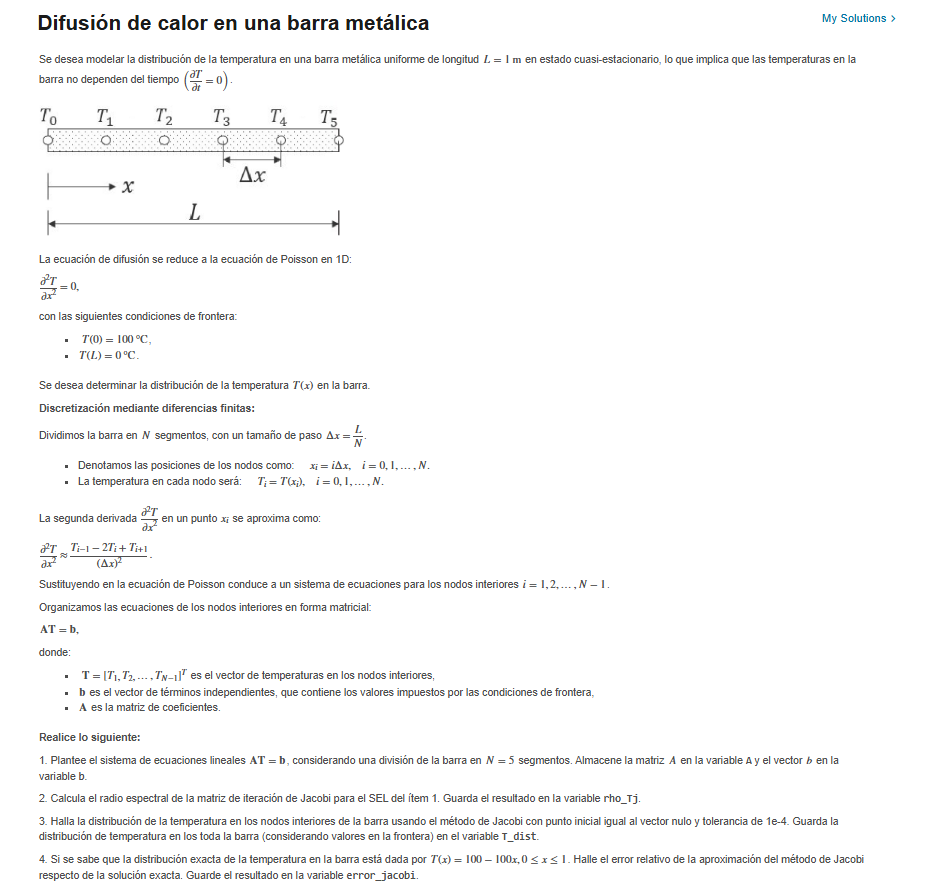

L = 1;         % Longitud de la barra
N = 5;         % Número de segmentos
dx = L / N;    % Tamaño del paso
T0 = 100;      % Temperatura en x = 0
TL = 0;        % Temperatura en x = L

% Construcción de la matriz A (tridiagonal correcta)
A = 2 * eye(N-1) + diag(-1 * ones(N-2, 1), 1) + diag(-1 * ones(N-2, 1), -1)

A =      2    -1     0     0
    -1     2    -1     0
     0    -1     2    -1
     0     0    -1     2



% Construcción del vector b con condiciones de frontera
b = zeros(N-1, 1);
b(1) = T0;    % Condición de frontera en el primer nodo
A

A =      2    -1     0     0
    -1     2    -1     0
     0    -1     2    -1
     0     0    -1     2


% Calcular el radio espectral (rho_Tj)
D = diag(diag(A));
L_mat = -tril(A, -1);
U_mat = -triu(A, 1);
Tj_matrix = inv(D) * (L_mat + U_mat);
rho_Tj = max(abs(eig(Tj_matrix)));

% Vector inicial y tolerancia para Jacobi
x0 = zeros(N-1, 1);
Tol = 1e-4;

% Método de Jacobi
[z, T_jacobi] = jacobi(A, b, x0, Tol);

% Distribución de temperaturas incluyendo condiciones de frontera
T_dist = [T0; T_jacobi; TL];

% Cálculo de la solución exacta T(x) = 100 - 100 * x
x_interior = (1:N-1) * dx;  % Puntos interiores
T_exacta = 100 - 100 * x_interior';

% Cálculo del error relativo del método de Jacobi
error_jacobi = norm(T_jacobi - T_exacta, inf) / norm(T_exacta, inf);

% Mostrar resultados
A

A =      2    -1     0     0
    -1     2    -1     0
     0    -1     2    -1
     0     0    -1     2


b

b =    100
     0
     0
     0


rho_Tj

rho_Tj =    0.809016994374948


T_dist

T_dist = 1.0e+02 *

   1.000000000000000
   0.799916753539947
   0.599833507079893
   0.399865304398190
   0.199897101716488
                   0


error_jacobi

error_jacobi =      2.081161501337192e-04



% --- Función del método de Jacobi ---
%{
function [z, x1] = jacobi(A, b, x0, Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A, -1);
    U = -triu(A, 1);
    Tj = inv(D) * (L + U);
    cj = inv(D) * b;
    i = 0;
    z = [i, x0', dr];
    while dr > Tol
        % Método numérico
        x1 = Tj * x0 + cj;
        % Calcular el error
        dr = norm(x1 - x0, 'inf') / norm(x1, 'inf');
        i = i + 1;
        z = [z; i, x1', dr];
        % Actualizar las variables previas
        x0 = x1;
 end
end

%}


P10

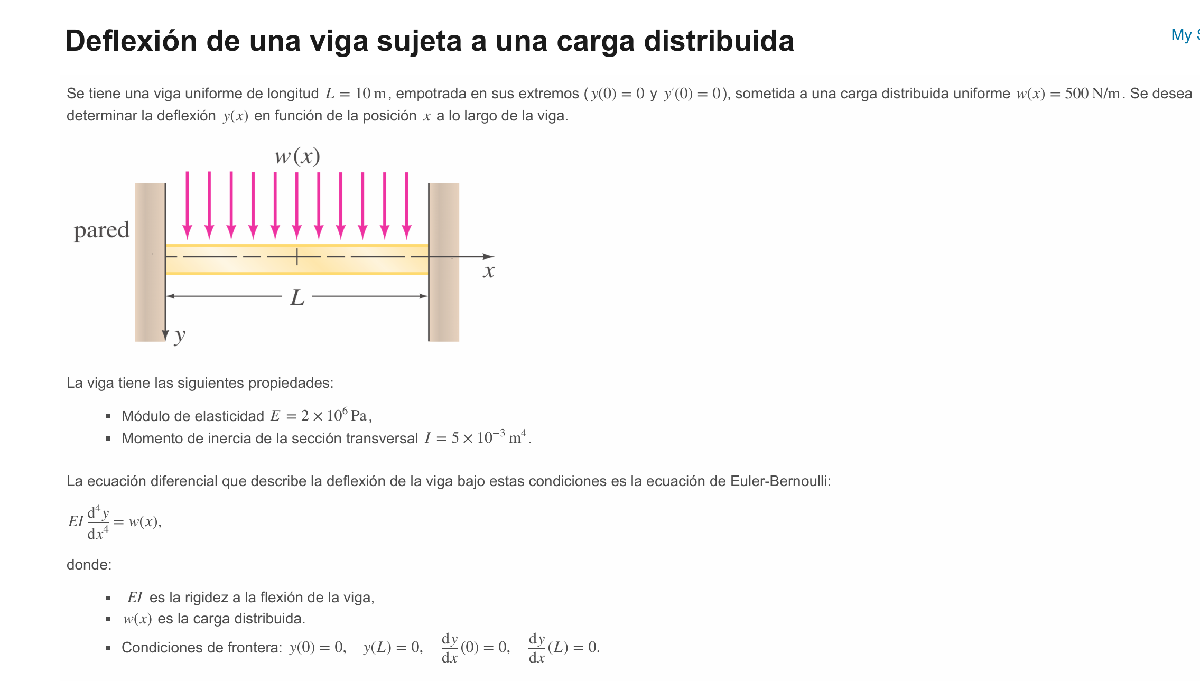

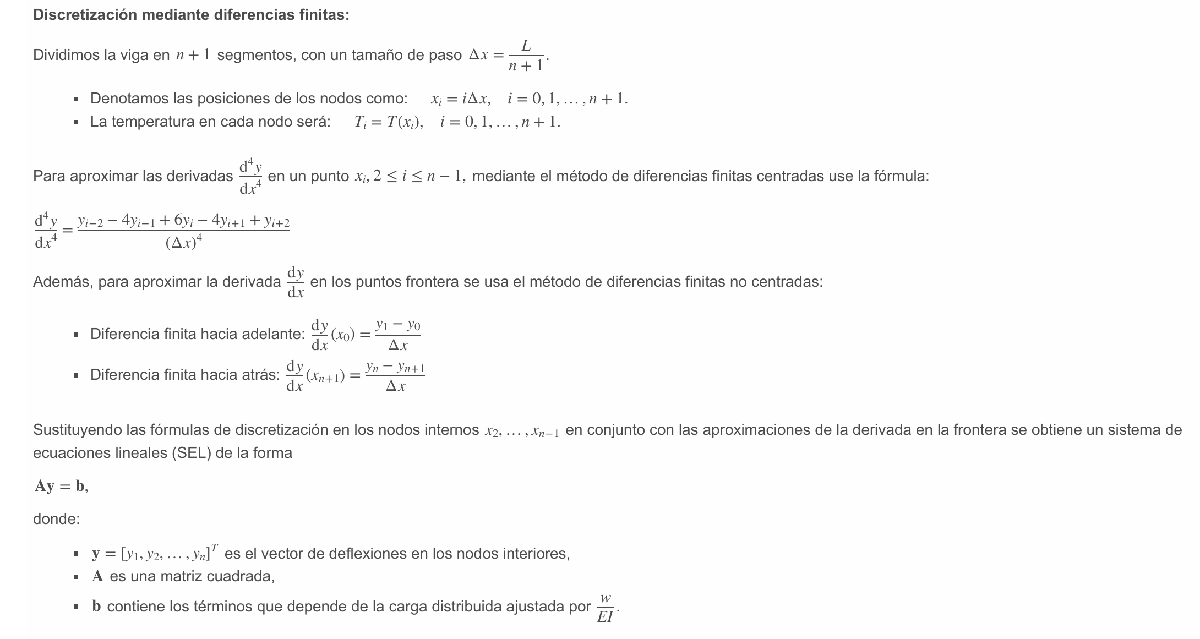

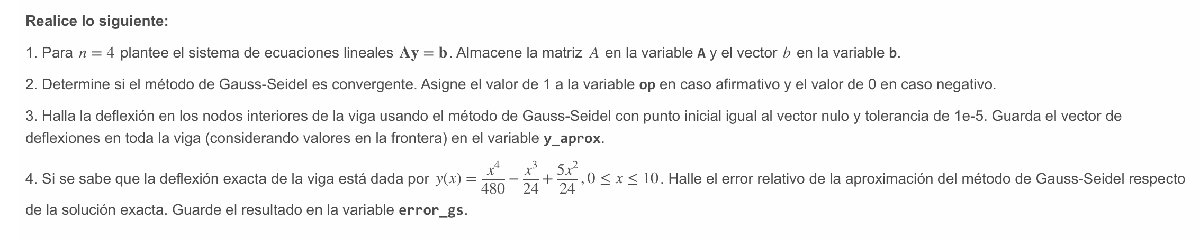

## Funciones

% 1

function [z,x1] = jacobi(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tj = inv(D)*(L+U);
    cj = inv(D)*b;
    i = 0;
    z = [i x0' dr];
    while(dr>Tol)
        % Método Numérico
        x1 = Tj*x0 + cj;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end

function [z,x1] = gauss_seidel(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tgs = inv(D-L)*(U);
    cgs = inv(D-L)*b;
    i = 0;
    z = [i x0' dr];
    while(dr>Tol)
        % Método Numérico
        x1 = Tgs*x0 + cgs;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end

function [z, T, c] = iterativo(A, b, x0, Tol, method)
    if nargin < 5
        method = 0; 
    end

    D = diag(diag(A));
    U = -triu(A,1);
    L = -tril(A,-1);

    if method == 0
        T = inv(D) * (L + U);
        c = inv(D) * b;
    elseif method == 1
        T = inv(D - L) * U;
        c = inv(D - L) * b;
    else
        error('Escoja un método válido')
    end

    er = 1;
    z = [x0' er];
    
    while er > Tol
        x1 = T * x0 + c;
        er = norm(x1 - x0, inf) / norm(x1, inf);
        z = [z; x1' er];
        
        x0 = x1;
    end
end